## Homework 2

**2411374 朱灏轩**

### Question

Given the parameters in the Lorenz Attractor equation:


$$\sigma=10; \beta=\frac{8}{3}; \rho=28$$


and the initial values at $t=0$:


$$x=-7; y=7; z=25$$


- Follow the process told to solve the Lorenz Attractor equation in the time window $[0, 100]$.

- Plot the result (trajectory) in 3D real space.

- Plot 2 Lorenz Attractor in the window $[0, 100]$. For the second one, increase the initial value of $y$ by $1.0\times10^{-6}$, and to observe the separation of their trajectories.

**Tip: use **`plot3(x, y, z, x2, y2, z2)`

### **Solution**

根据题设条件定义模型参数

global sigma beta rho
sigma = 10;
beta = 8/3;
rho = 28;
T = 100;
phi0 = [-7; 7; 25];

Lorenz Attractor方程如下所示：


$$\left\lbrace \begin{array}{l}
x^{\prime } =\sigma \left(y-x\right)\\
y^{\prime } =x\left(\rho -z\right)-y\\
z^{\prime } =\textrm{xy}-\beta z
\end{array}\right.$$
 

根据Lorenz Attractor方程定义函数`LorenzAttr`

**注：MATLAB R2024a版本引入新特性，可以在脚本和实时脚本中任意位置定义函数。**

**参见：**[**https://ww2.mathworks.cn/products/new_products/release2024a.html**](https://ww2.mathworks.cn/products/new_products/release2024a.html)

function dphidt = LorenzAttr(t, phi)
    global sigma beta rho;
    dphidt = [sigma*(phi(2)-phi(1));        % dx/dt = sigma * (y-x)
              phi(1)*(rho-phi(3))-phi(2);   % dy/dt = x * (rho-z) - y
              phi(1)*phi(2)-beta*phi(3)];   % dz/dt = x * y - beta * z
end

调用`ode45`解上述方程

[t, phi] = ode45(@LorenzAttr, [0, T], phi0);

使用`plot3`在三维实空间中绘制Lorenz Attractor方程图像

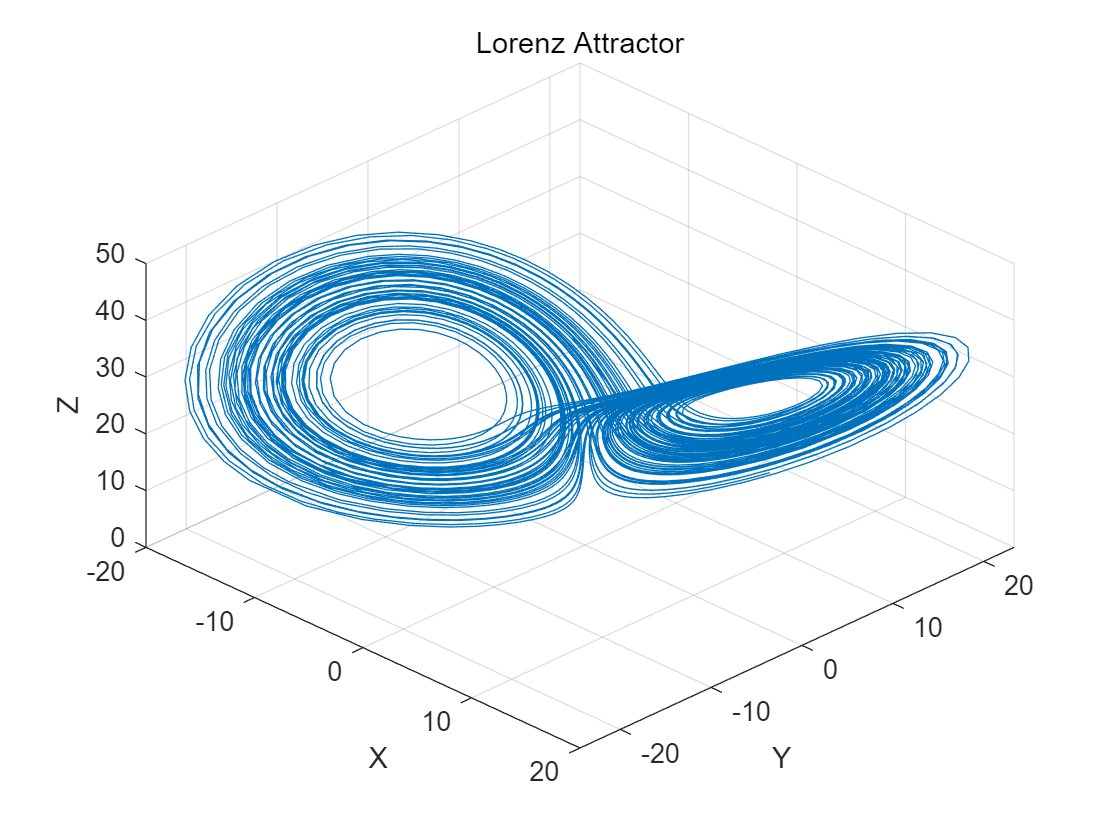

figure;
plot3(phi(:,1), phi(:,2), phi(:,3));
title("Lorenz Attractor");

xlabel("X");
ylabel("Y");
zlabel("Z");
grid on;
view([45 45]);

更改初始值，在图像上叠加另一个Lorenz Attractor轨迹

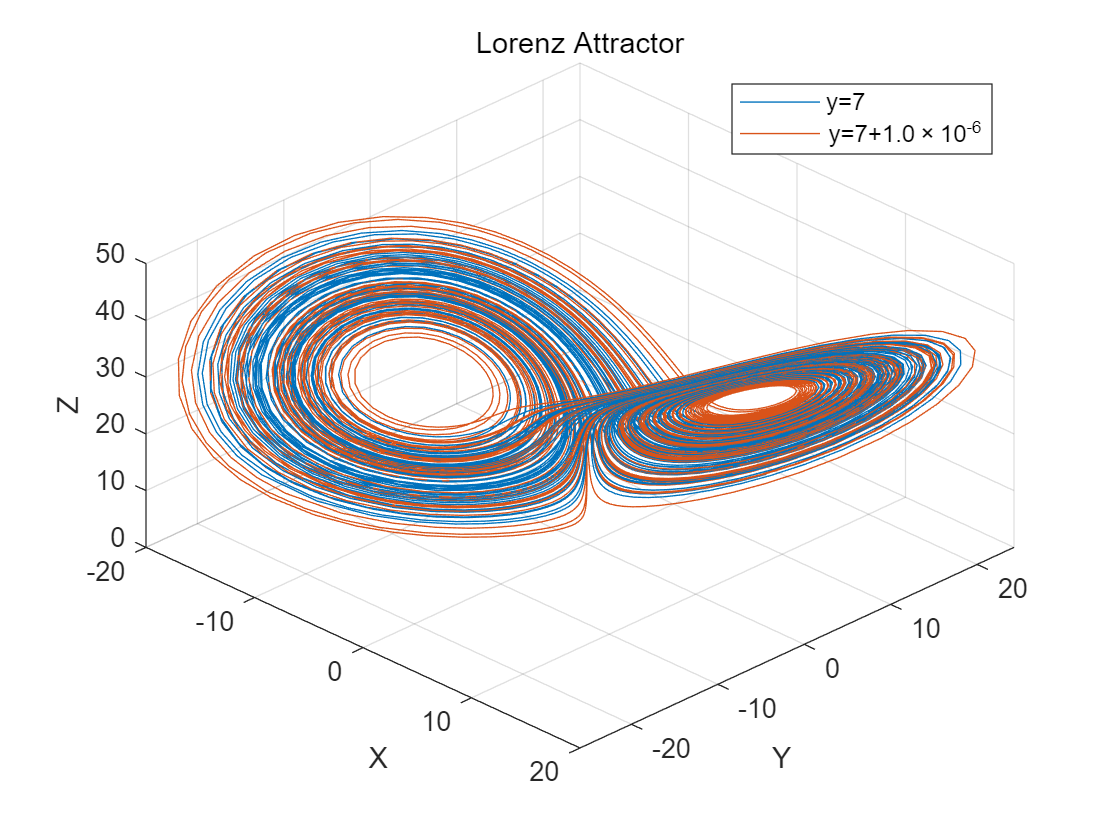

delta = [0; 1e-6; 0]; % 第二条轨迹初始值偏移量
phi0New = phi0 + delta;
[t, phiNew] = ode45(@LorenzAttr, [0, T], phi0New);
figure;
plot3(phi(:,1), phi(:,2), phi(:,3), phiNew(:,1), phiNew(:,2), phiNew(:,3));
legend(["y=7", "y=7+1.0\times10^{-6}"], Interpreter="tex", Location="northeast");
title("Lorenz Attractor");
xlabel("X");

ylabel("Y");
zlabel("Z");
grid on;
view([45 45]);